# DATA1: Cublical Complex

% GOAL: Investigating cyclic interaction between multiple time-varying signals
% using the mathemtical ground truth. To do so, we need to
% design a simulation (toy example), where underlying signal has cycles from 
% the start.
% 
% MINIGOAL: We will learn AI-aided coding and building a new  data structure. 
%
% (c) 2026 Moo K. Chung
% University of Wisconsin-Madison

%% Building a grid as 2D cell complex. 
% A cell complex is a combinatorial representation of a space 
% composed of nodes (0-simplices), edges connecting pairs of nodes 
% (1-simplices), and filled-in faces (2-cells) bounded by closed loops of edges. 
% In a two-dimensional grid, each face is typically a square bounded 
% by four edges, explicitly encoding local surface structure beyond pairwise 
% connectivity.

% Such a data structure is not natively supported in MATLAB. 
% We therefore first construct a cell complex data structure to 
% explicitly represent nodes, edges, and faces.
clear; clc;
%S = cellcomplex_build(4, 5);
%figure; cellcomplex_display(S)

S = cellcomplex_build_checkerbaord(4,4)

S = struct with fields:
    nodes: [25×2 double]
    edges: [40×2 double]
    faces: [1×1 struct]


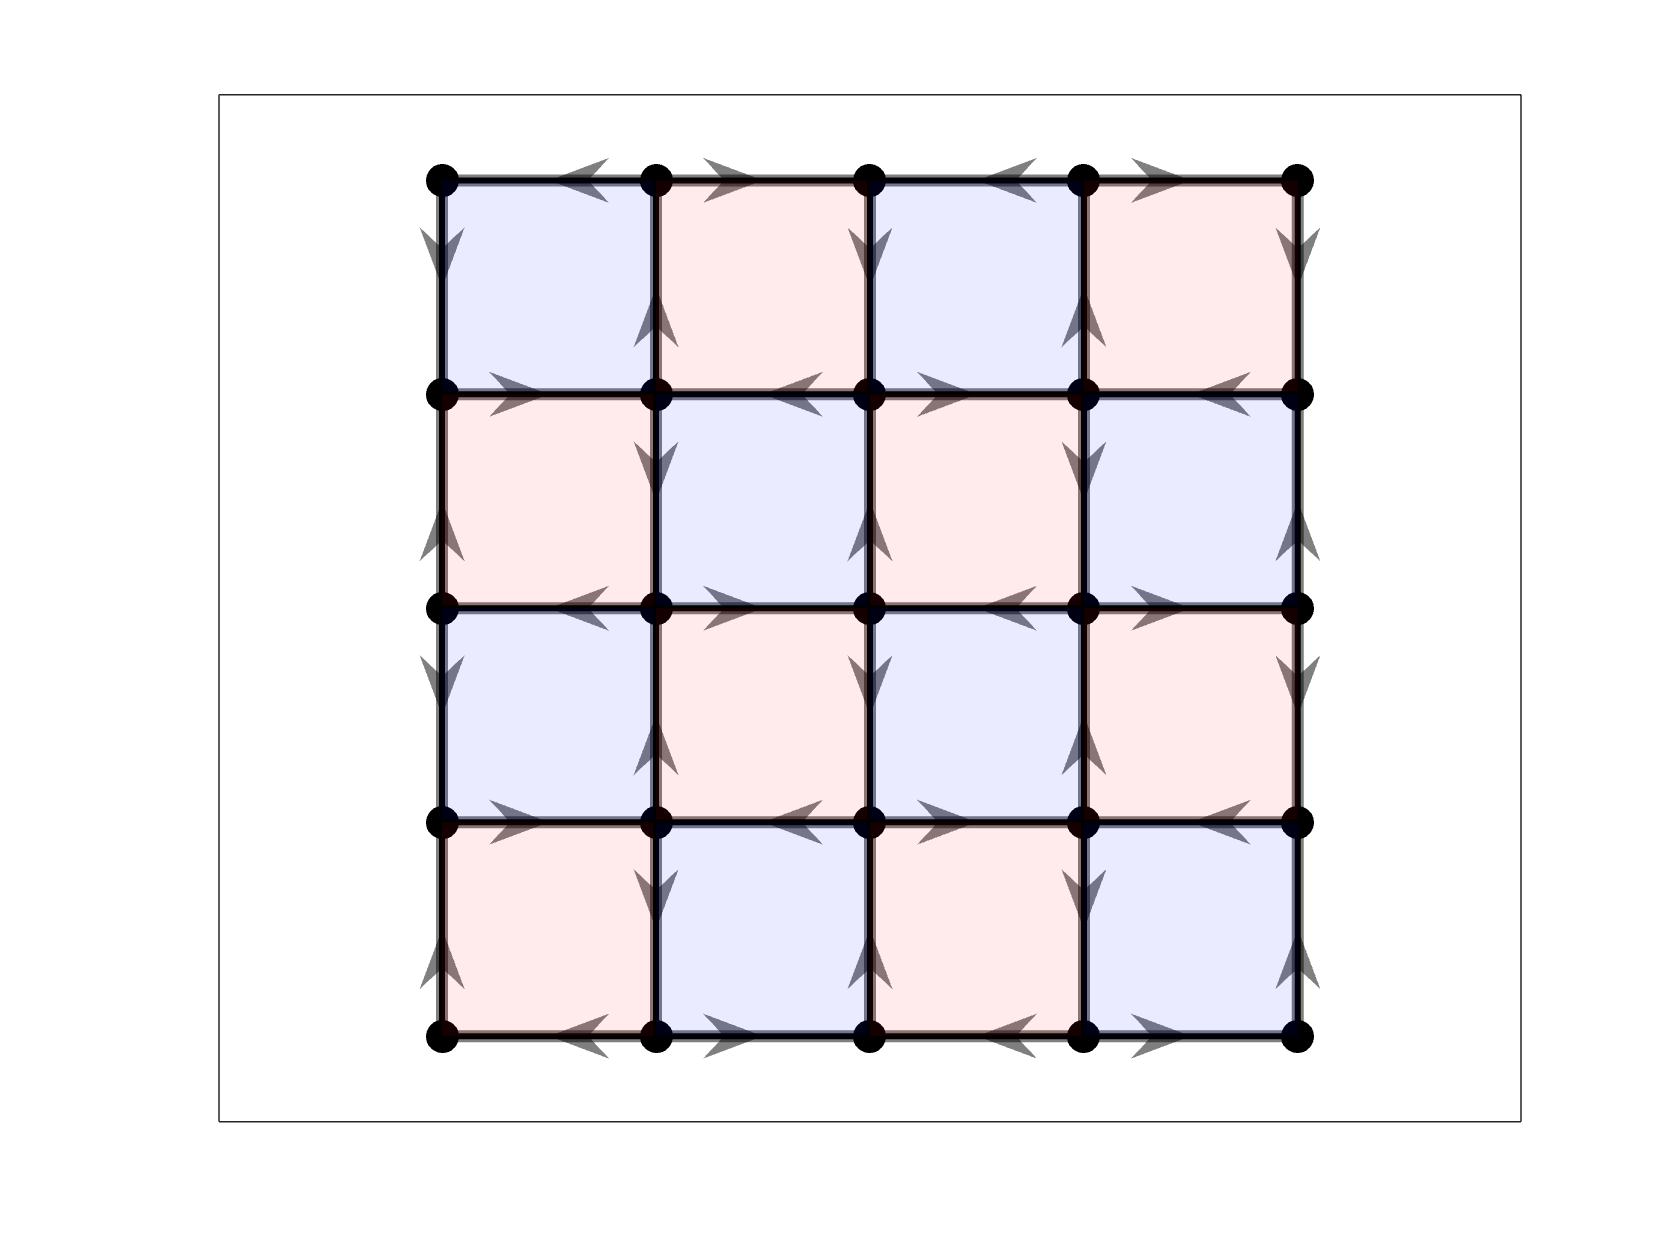

figure; cellcomplex_display(S)


%AI Sanity check - check if AI followed edge indexing in S.faces.edges.   
cellcomplex_summary(S)


CELL COMPLEX SUMMARY
  #nodes (K)  : 25
  #edges (E)  : 40
  #faces (F)  : 16
  Euler chi   : 1  (K - E + F)
  #components : 1
  Betti-1 (cycle rank)  : 16  (E - K + #components)
  faces CW    : 8
  faces CCW   : 8
  faces mixed : 0
  flow field  : no
  cycles      : no



ans = struct with fields:
                     K: 25
                     E: 40
                     F: 16
                   chi: 1
             nConnComp: 1
            cyclomatic: 16
              nFacesCW: 8
             nFacesCCW: 8
    nFacesInconsistent: 0
               hasFlow: 0
             hasCycles: 0


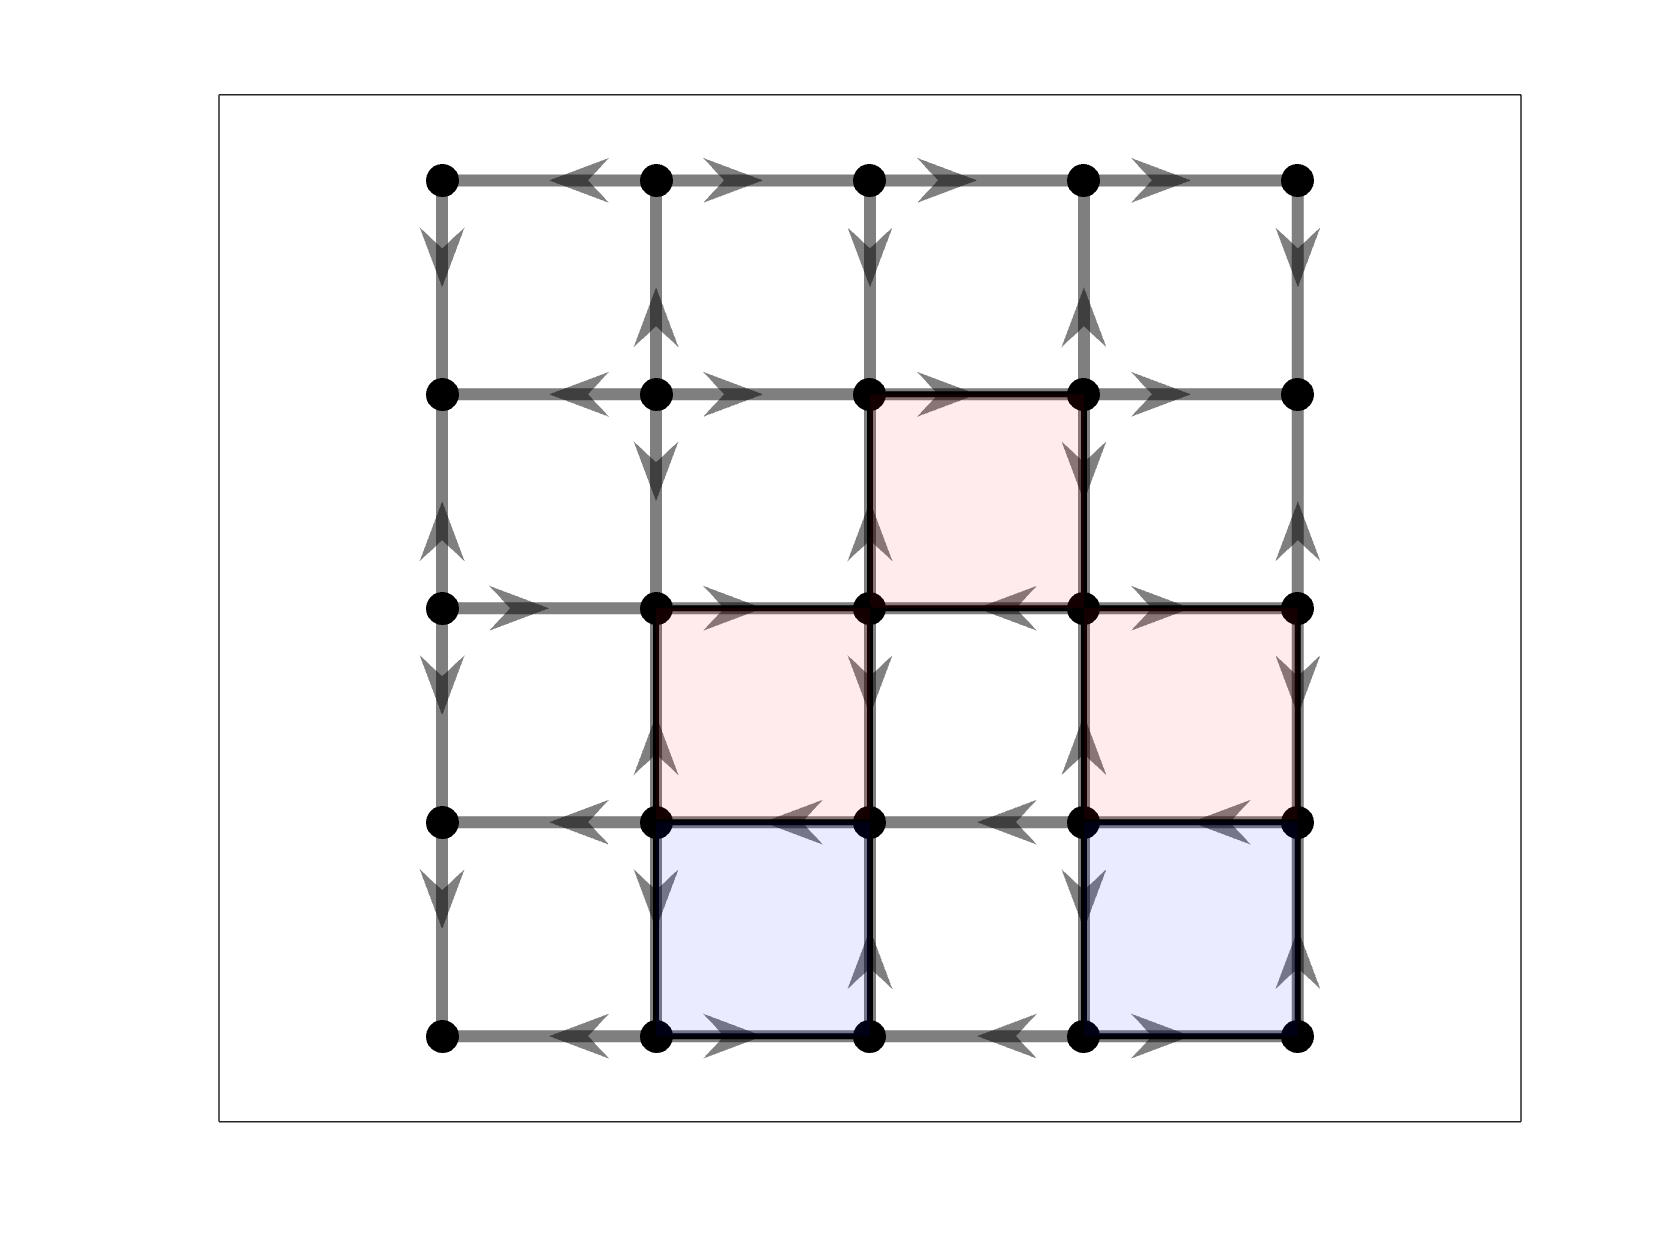


%We will perturb the direction of edges with probability p
seed =1; %random number seed
p = 0.4; %fraction of perturbation
Sp = cellcomplex_perturb_edges(S, p, seed); %by default edge directions are randomly pertrubed. 
figure; cellcomplex_display(Sp)

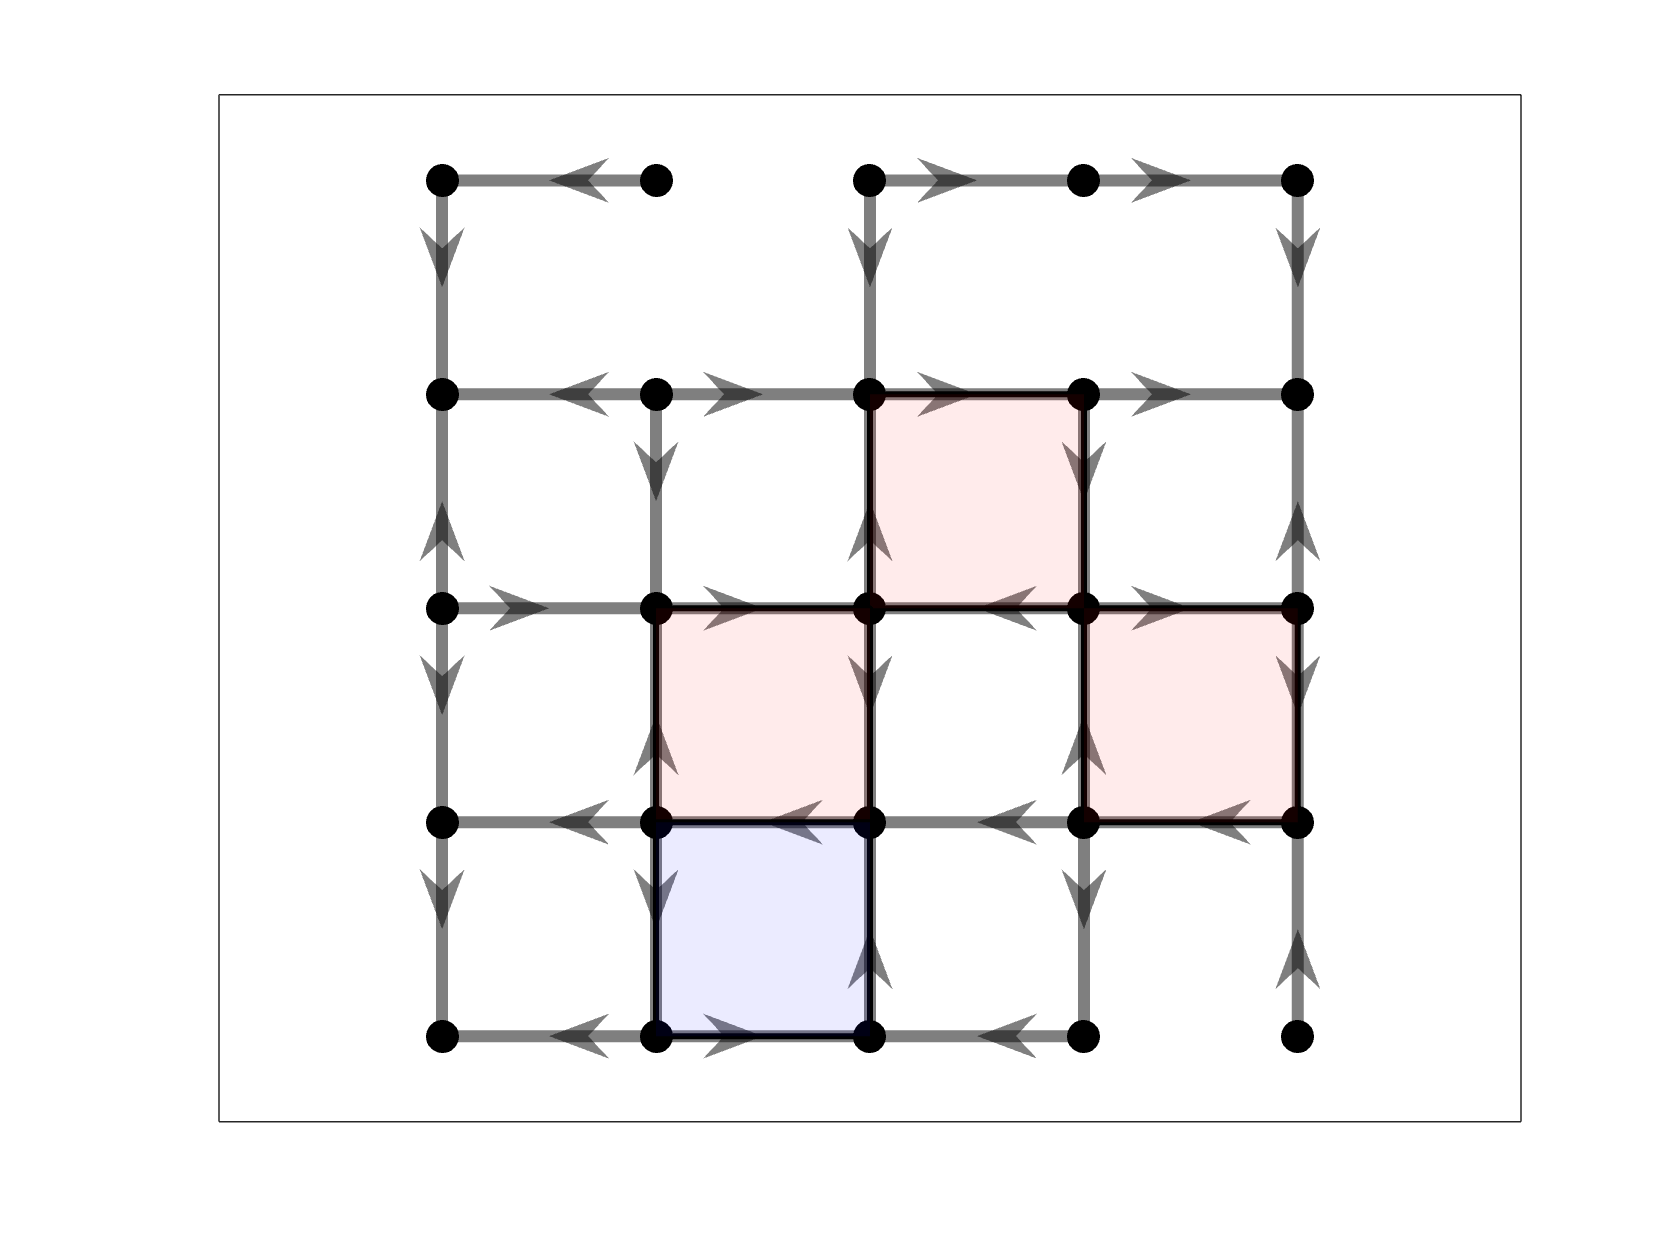


% We will perform edge deletion operation to make the shape more complex. 
% An Erdős–Rényi (ER) random graph model introduces randomness by deciding 
% whether each edge is present independently with a fixed probability p. 
% In the classical G(n,p) model, any pair of nodes amng n-nodes can be 
% connected with probability p. In our setting, randomness is applied in 
% an ER-type manner by independently removing each edge of a fixed grid with 
% probability p.

seed = 2; %random number seed
Spr = cellcomplex_remove_edges(Sp, 0.1, seed);
figure; cellcomplex_display(Spr);


% Introduce flow field on the cell complex. 
% Scalar data on edeges. Default flow will be simply the current edge orientation. 
Sprf = cellcomplex_flow (Spr);
figure; cellcomplex_display(Sprf);

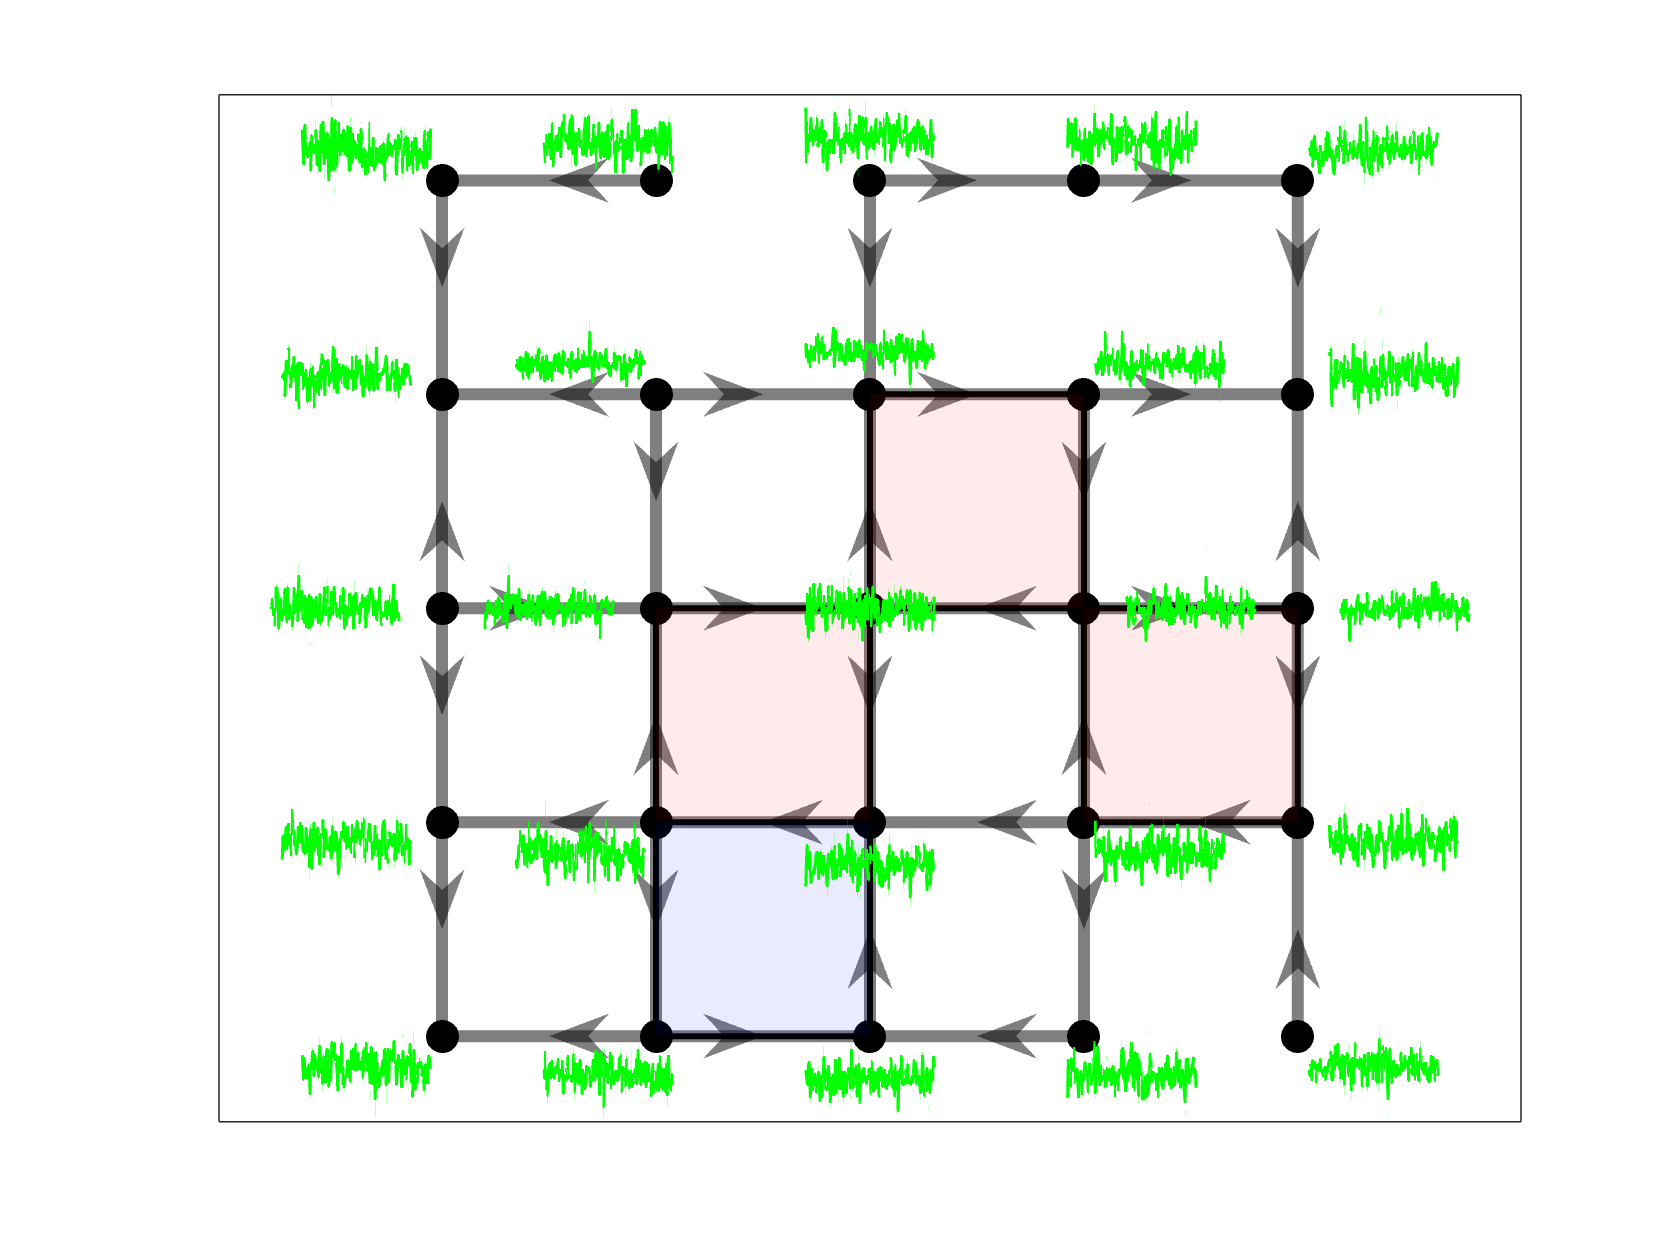


% Genearte time series that follows the given flow pattern. 
% The model is based on Vector Auto regressive (VAR) model, which we will study in one lecture.  
p=4; noise_level = 1;
edges= Sprf.edges;
flows= Sprf.flows;
Z = VAR_graph(edges,flows, p, noise_level); % Used existing codes written for 2025 class. 

figure; cellcomplex_display(Sprf);
graph_overlay_timeseries(Sprf.nodes, Z);

# DATA 9 (Project 15): **2-dimensional simplicial complex.**

% Unlike other data/projects, the act of generating the data structure itself constitutes 
% both the dataset and the project.
% 
% Goal: The goal of this project is to construct and analyze a two-dimensional simplicial
% complex built from equilateral triangles in the plane. Motivated by square-grid-based 
% cubical complexes (DATA 1), this project extends the framework to triangular meshes and 
% explores how topological invariants, such as Betti numbers and Euler characteristic, 
% behave under simplicial construction. Students will investigate how the choice of 
% building blocks (squares versus triangles) influences connectivity, cycles, and
% higher-dimensional structure.
%
% Description: Unlike other projects, this project treats the construction of the data 
% structure itself as both the dataset and the central project task. Students will build 
% a complete two-dimensional simplicial complex on an equilateral triangular lattice and 
% encode it into a structured computational representation. The vertices, edges, and 
% triangular faces that are generated form the primary data object. The emphasis is not 
% merely on drawing a triangular mesh, but on designing a rigorous and reusable data 
% structure that satisfies the mathematical definition of a simplicial complex.
%
% Beyond correct construction, the data structure must support algebraic operations. 
% Students should design the simplicial complex so that it behaves like a combinatorial 
% object on which operations can be performed. This includes defining meaningful addition 
% and subtraction of complexes, such as union and symmetric difference of faces or edges,
% and enabling multiplication-like operations when appropriate, such as scalar weighting 
% of simplices. The representation should therefore allow vector-space–like manipulations 
% on simplices while preserving structural consistency. The goal is to move from a static
% geometric drawing to an algebraically manipulable topological object.
%
% After establishing this algebraic framework, students will investigate statistical 
% properties of simplicial complexes generated through random sampling. For example, 
% triangles may be included or excluded according to a probability model, producing 
% random subcomplexes of the triangular lattice. Students will analyze how topological 
% quantities such as the number of connected components, cycle counts, and Euler 
% characteristic vary under random perturbations. By repeatedly sampling complexes and 
% computing their invariants, students will examine distributions, variability, and 
% phase-transition–like behavior in topology as sampling probability changes. 
% This connects combinatorial topology with probabilistic modeling and statistical 
% analysis.
%
% Learning Outcomes: Students will understand how simplicial complexes can be treated 
% as algebraic objects that support structured operations beyond simple visualization. 
% They will gain experience designing data structures that allow vector-like manipulation 
% of simplices while maintaining mathematical validity. Students will also learn how to 
% investigate the statistical behavior of topological invariants under random sampling,
% developing intuition about variability, robustness, and structural transitions in 
% discrete geometric models. Through this integration of algebra, topology, 
% and probability, they will appreciate how topological data structures can serve as 
% both deterministic mathematical objects and stochastic models for complex systems.